% FACS Histogram Simulation with Gating

% Parameters
numCells1 = 5000;  % Number of cells in population 1
numCells2 = 5000;  % Number of cells in population 2
meanFluorescence1 = 75;  % Mean fluorescence of population 1
meanFluorescence2 = 100; % Mean fluorescence of population 2
stdDev1 = 10;  % Standard deviation of fluorescence for population 1
stdDev2 = 15;  % Standard deviation of fluorescence for population 2

% Simulate two populations of cells
pop1 = meanFluorescence1 + stdDev1 * randn(numCells1, 1);
pop2 = meanFluorescence2 + stdDev2 * randn(numCells2, 1);

% Combine the populations
combinedPop = [pop1; pop2];

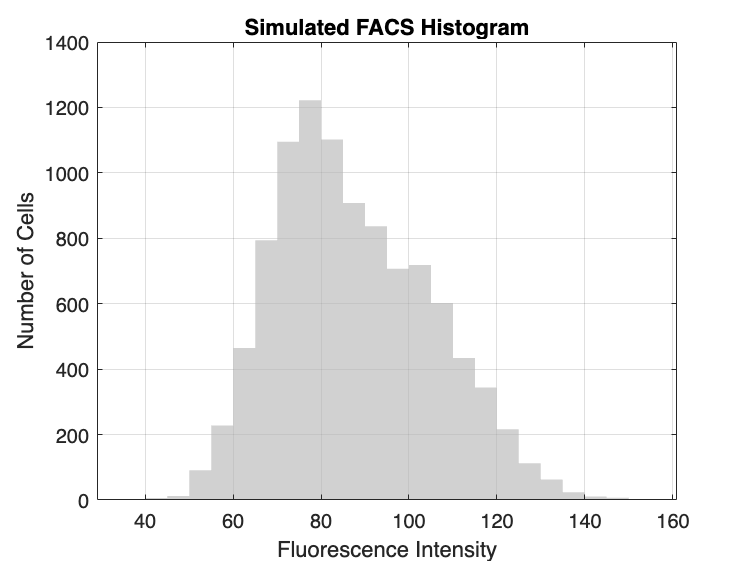

% Plot histogram
figure;
histogram(combinedPop, 'BinWidth', 5, 'FaceColor', [0.7, 0.7, 0.7], 'EdgeColor', 'none');
xlabel('Fluorescence Intensity');
ylabel('Number of Cells');
title('Simulated FACS Histogram');
grid on;

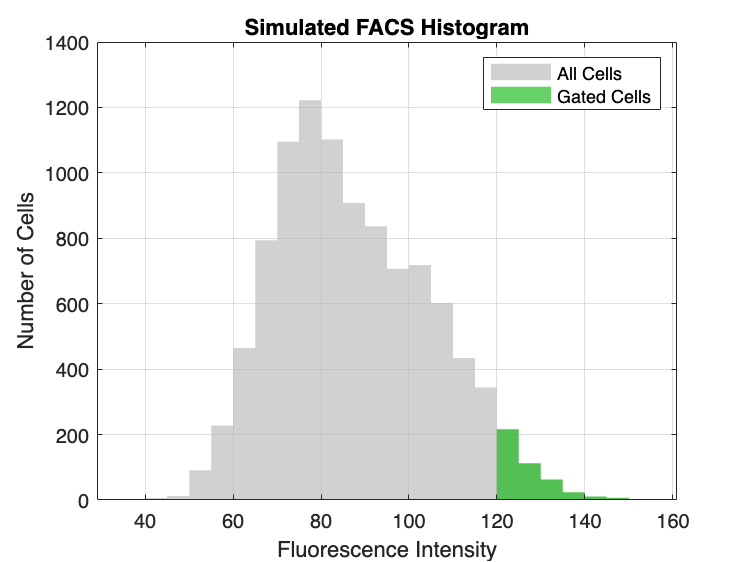

% Gating
gateMin = 120; % Minimum fluorescence for gate
gateMax = 180; % Maximum fluorescence for gate

% Find cells within the gate
gatedCells = combinedPop(combinedPop >= gateMin & combinedPop <= gateMax);

% Highlight gated region on the histogram
hold on;
histogram(gatedCells, 'BinWidth', 5, 'FaceColor', [0, 0.7, 0], 'EdgeColor', 'none');
legend('All Cells', 'Gated Cells');


% Print number of gated cells
fprintf('Number of cells in gated region: %d\n', length(gatedCells));

Number of cells in gated region: 434
